# Pre-Processing MI 

write eeglab() in Command Window (Matlab)

## Load data

Load data "B0402T.gdf" (data stored in .gdf file (general data format for biomedical signal)) ไฟล์นี้สามารถเปิดได้จาก toolbox : biosig

`sload` function : biosig toolbox

s : เก็บค่าข้อมูลต่อเนื่อง

h : เก็บค่ารายละเอียดข้อมูล

[s, h] = sload('B0402T.gdf'); %1

stored important data ex. Sampling rate and time of signal structure (เวลาของสัญญาณไว้ใช่ในัวแปรเชิงโครงสร้าง)

eeg = struct();
eeg.fs = h.SampleRate;

%classify types of MI which MI class1 and MI class2
class1_MI = h.TRIG(find(h.Classlabel==1));
class2_MI = h.TRIG(find(h.Classlabel==2));

for i=1:length(h.Classlabel)
    if i<= length(h.Classlabel)/2
        eeg.data(:,:,i) = [s((class1_MI(i)+3.5*eeg.fs:class1_MI(i)+5.499*eeg.fs), 1:3)];
    else
        k = i-(length(h.Classlabel)/2);
        eeg.data(:,:,i) = [s((class2_MI(k)+3.5*eeg.fs:class2_MI(k)+5.499*eeg.fs), 1:3)];
    end
end
%time 0-9 sec
eeg.time = (0:length(eeg.data)-1);

%filter
for i=1:length(h.Classlabel)
    for j=1:3
        x_value = eeg.data(:,j,i);
        eeg.fil_data(:,j,i) = bp_filter(4, 8,30, eeg.fs, x_value);
    end
end 
% trial_name = {};
% for i=1:length(h.Classlabel)
%     trial_name = [trial_name, sprintf('trial_%d', i)];
% end
% for i=1:length(h.Classlabel)
%     mkdir(trial_name{i});
% end

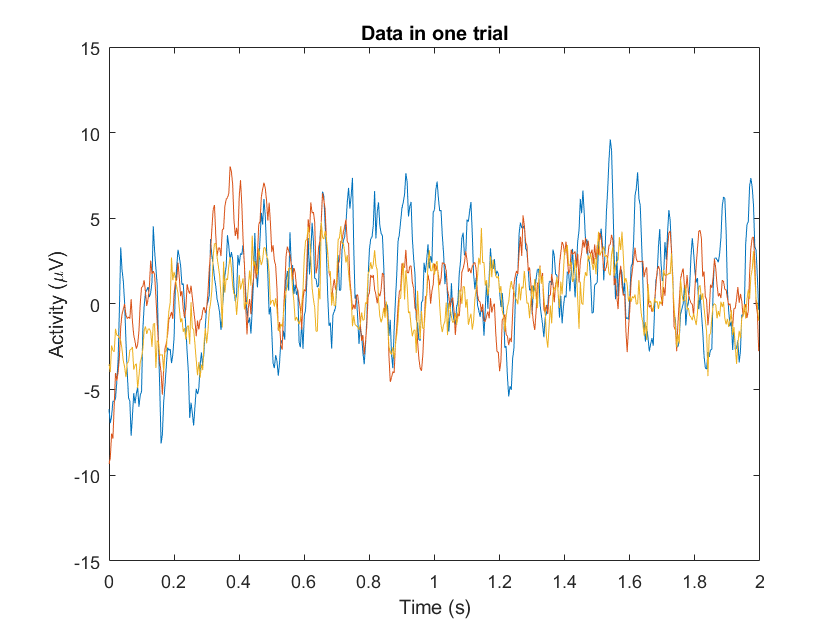

%Visualize all data
figure(2), clf
plot(eeg.time/eeg.fs, eeg.data(:,:,1));
xlabel('Time (s)'), ylabel('Activity (\muV)');
xlim([0 2]);
ylim([-15 15]);
title('Data in one trial');

## Visualize data in First trial

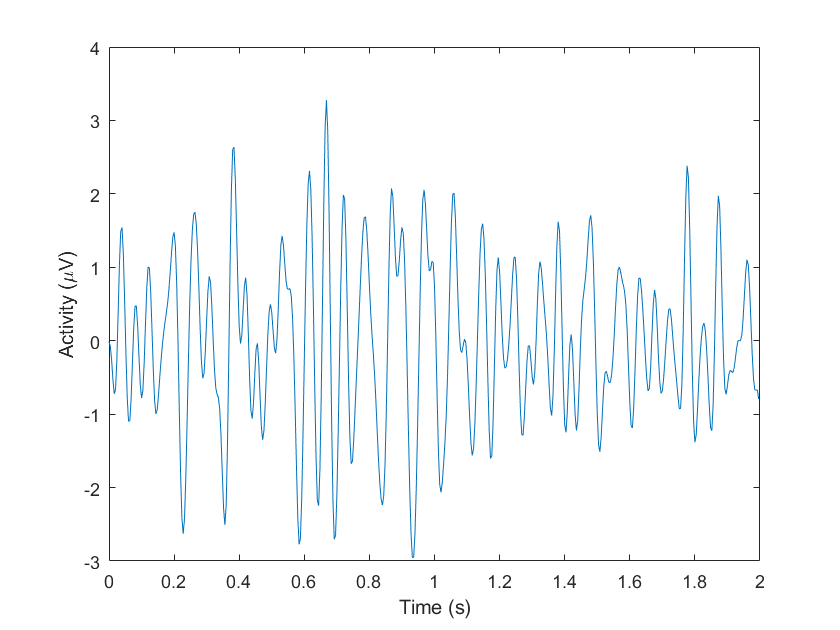

figure(3), clf
plot(eeg.time/eeg.fs, eeg.fil_data(:,3,1));
xlabel('Time (s)');
ylabel('Activity (\muV)');

% figure(1)
% plot(eeg.time/eeg.fs, eeg.data(:,:,1));
% xlabel("Time (s)");
% ylabel("Activity (\muV)");
% xlim([0 9]);
% ylim([-30 30]);
% title('Data in one trial');

## Calculating signal from equations

Left hand

%LEFT HAND
%EEG_AVG
for i=1:length(h.Classlabel)
    eeg_avg_left = sum(eeg.fil_data(:,:,1:60).^2, 3) / (length(h.Classlabel)-60);
end
%EEG_REF
for i=1:3
   eeg_ref_left(:,i) = sum(eeg_avg_left(1:500,i),1) / 500;
end
%ERD/ERS
for i=1:3
    erp_left(:,i) = ((eeg_avg_left(:,i) - eeg_ref_left(i)) / eeg_ref_left(i)) * 100;
end

Right hand

%Right HAND
%EEG_AVG
for i=1:length(h.Classlabel)
    eeg_avg_right = sum(eeg.fil_data(:,:,61:120).^2, 3) / (length(h.Classlabel)-60);
end
%EEG_REF
for i=1:3
   eeg_ref_right(:,i) = sum(eeg_avg_right(1:500,i),1) / 500;
end
%ERD/ERS
for i=1:3
    erp_right(:,i) = ((eeg_avg_right(:,i) - eeg_ref_right(i)) / eeg_ref_right(i)) * 100;
end

%moving average filter
B = 1/20 * ones(20,1);
erp_left = filter(B,1,erp_left);
erp_right = filter(B,1,erp_right);

เลือกสัญญาณในช่วง 3.5 - 5.5 วินาที่ ซึ่งเป็นช่วงเวลาที่ทำการทดลอง

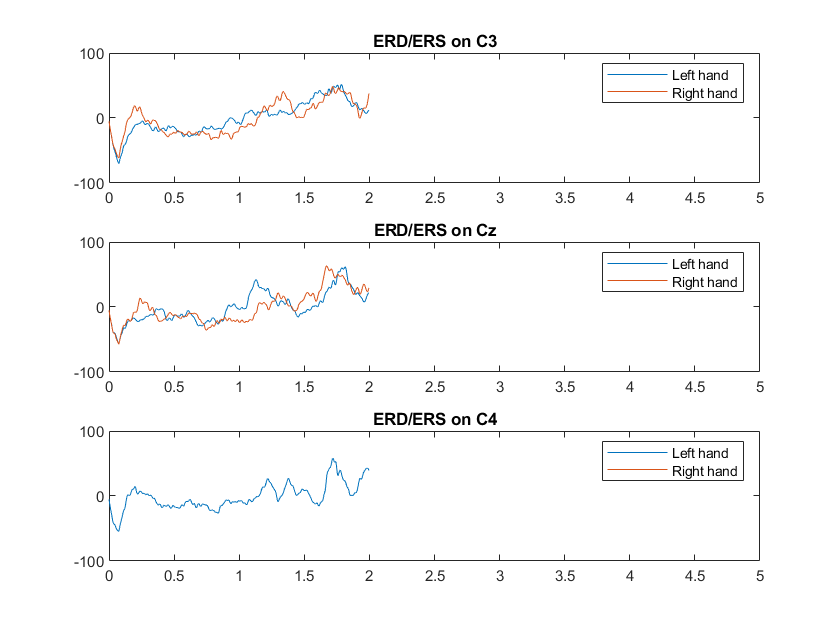

eeg = struct();
eeg.fs = h.SampleRate;

%classify types of MI which MI class1 and MI class2
class1_MI = h.TRIG(find(h.Classlabel==1));
class2_MI = h.TRIG(find(h.Classlabel==2));

for i = 1:length(h.Classlabel)
    if i <= (length(h.Classlabel)/2)
        eeg.data(:,:,i) = [s((class1_MI(i) + 3.5*eeg.fs : class1_MI(i)+5.4999*eeg.fs), 1:3)];
    else
        k = i-(length(h.Classlabel)/2); 
        eeg.data(:,:,i) = [s((class2_MI(k) + 3.5*eeg.fs : class2_MI(k)+5.4999*eeg.fs), 1:3)];
    end
end
%time 0-9 sec
eeg.time = (0:length(eeg.data)-1);

for i=1:length(h.Classlabel)
    for j=1:3
        x_value = eeg.data(:,j,i);
        eeg.fil_data(:,j,i) = bp_filter(4, 8,30, eeg.fs, x_value);
    end
end

%LEFT HAND
%EEG_AVG
for i=1:length(h.Classlabel)
    eeg_avg_left = sum(eeg.fil_data(:,:,1:60).^2, 3) / (length(h.Classlabel)-60);
end
%EEG_REF
for i=1:3
   eeg_ref_left(:,i) = sum(eeg_avg_left(1:500,i),1) / 500;
end
%ERD/ERS
for i=1:3
    erp_left(:,i) = ((eeg_avg_left(:,i) - eeg_ref_left(i)) / eeg_ref_left(i)) * 100;
end


%Right HAND
%EEG_AVG
for i=1:length(h.Classlabel)
    eeg_avg_right = sum(eeg.fil_data(:,:,61:120).^2, 3) / (length(h.Classlabel)-60);
end
%EEG_REF
for i=1:3
   eeg_ref_right(:,i) = sum(eeg_avg_right(1:500,i),1) / 500;
end
%ERD/ERS
for i=1:3
    erp_right(:,i) = ((eeg_avg_right(:,i) - eeg_ref_right(i)) / eeg_ref_right(i)) * 100;
end

B = 1/20 * ones(20,1);
erp_left = filter(B,1,erp_left);
erp_right = filter(B,1,erp_right);
%plotting
sizewin = 100;
figure(2)
subplot(3,1,1)
plot(eeg.time/eeg.fs, erp_left(:,1), eeg.time/eeg.fs, erp_right(:,1));
xlim([0 5])
ylim([-sizewin sizewin])
title(['ERD/ERS on C3']);
legend('Left hand', 'Right hand')
subplot(3,1,2)


plot(eeg.time/eeg.fs, erp_left(:,2), eeg.time/eeg.fs, erp_right(:,2));
xlim([0 5])
ylim([-sizewin sizewin])
title(['ERD/ERS on Cz']);
legend('Left hand', 'Right hand')
subplot(3,1,3)
plot(eeg.time/eeg.fs, erp_left(:,3), eeg.time/eeg.fs, erp_right(:,3));
xlim([0 5])
ylim([-sizewin sizewin])
title(['ERD/ERS on C4']);
legend('Left hand', 'Right hand')

eeg_final = eeg.fil_data;
eeg_time = (1:length(eeg_final))/eeg.fs;

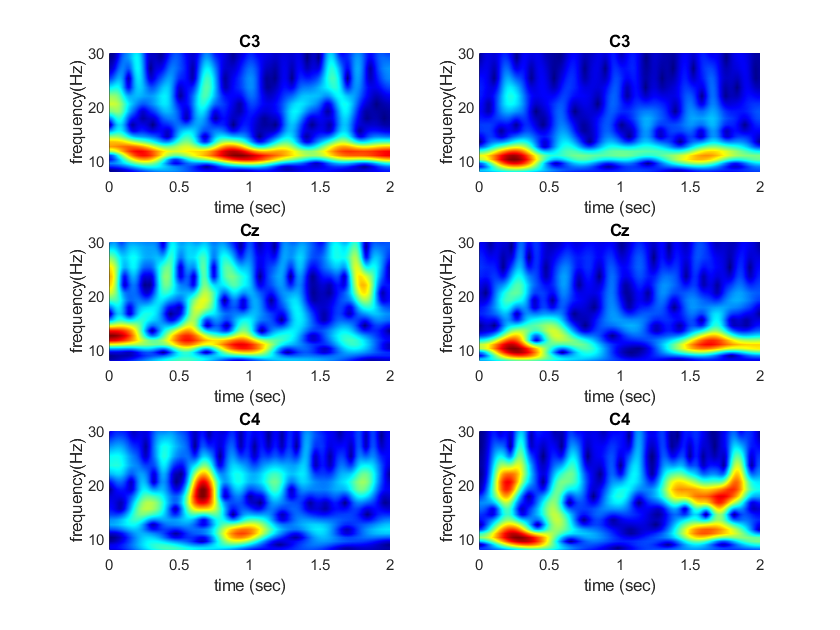

clf;
k = 1;right = 61;

figure()
subplot(3,2,1);
sig = eeg_final(:,1,k);
colormap jet;
[cfs,frq] = cwt(sig,eeg.fs);
pcolor(eeg_time, frq, abs(cfs));
shading interp; axis 'auto xy';
ylim([8 30]);xlim([0 2*eeg.fs]/eeg.fs);
xlabel("time (sec)");ylabel("frequency(Hz)");
title("C3")

subplot(3,2,3)
sig = eeg_final(:,2,k);
[cfs,frq] = cwt(sig,eeg.fs);
pcolor(eeg_time, frq, abs(cfs));shading interp; axis 'auto xy';
ylim([8 30]);xlim([0 2*eeg.fs]/eeg.fs);
xlabel("time (sec)");ylabel("frequency(Hz)");
title("Cz")

subplot(3,2,5)
sig = eeg_final(:,3,k);
[cfs,frq] = cwt(sig,eeg.fs);
pcolor(eeg_time, frq, abs(cfs));shading interp; axis 'auto xy';
ylim([8 30]);xlim([0 2*eeg.fs]/eeg.fs);
xlabel("time (sec)");ylabel("frequency(Hz)");
title("C4");

subplot(3,2,2);
sig = eeg_final(:,1,right);
[cfs,frq] = cwt(sig,eeg.fs);
pcolor(eeg_time, frq, abs(cfs));shading interp; axis 'auto xy';
ylim([8 30]);xlim([0 2*eeg.fs]/eeg.fs);
xlabel("time (sec)");ylabel("frequency(Hz)");
title("C3")

subplot(3,2,4)
sig = eeg_final(:,2,right);
[cfs,frq] = cwt(sig,eeg.fs);
pcolor(eeg_time, frq, abs(cfs));shading interp; axis 'auto xy';
ylim([8 30]);xlim([0 2*eeg.fs]/eeg.fs);
xlabel("time (sec)");ylabel("frequency(Hz)");
title("Cz")

subplot(3,2,6)
sig = eeg_final(:,3,right);
[cfs,frq] = cwt(sig,eeg.fs);
pcolor(eeg_time, frq, abs(cfs));shading interp; axis 'auto xy';
ylim([8 30]);xlim([0 2*eeg.fs]/eeg.fs);
xlabel("time (sec)");ylabel("frequency(Hz)");
title("C4");

#### Butterworth filter function

ตัวกรองที่ใช้ประมวลผลสัญญาณเพื่อให้สัญญาณที่ถูกกรองมีความถี่เรียบสุดที่เป็นไปได้ในช่วง bandpass

order = ลำดับของตัวกรอง

fcutlow,fcuthigh = ความถี่ต่ำสุดและสูงสุดของ bandpass

function filtered_signal = bp_filter(order,foutlow,fouthigh,fs,signal)
[b,a] = butter(order,[foutlow,fouthigh]/(fs/2),"bandpass");
cnt_fil = filter(b,a,signal);
filtered_signal = cnt_fil;
end